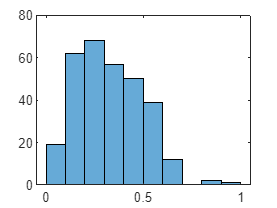

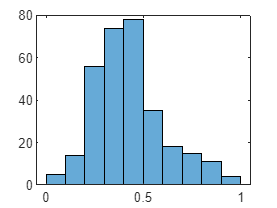

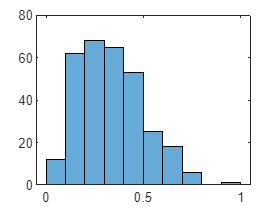

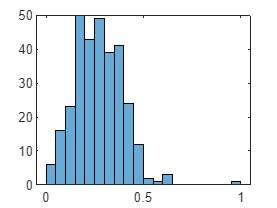

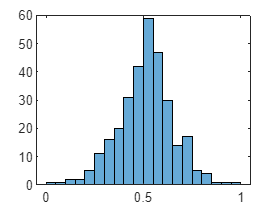

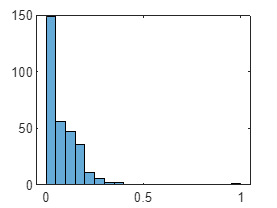

clear all; close all; clc

% data = readtable('column_2C.dat');
data = readtable('column_3C.dat');

labels = data(:,end);
features = data(:,1:end-1);
features = table2array(features);
aux = table2cell(labels);
labels = [];

for i=1:1:length(aux)
    labels{i,1} = cell2mat(aux(i));
end

[rowf,colf] = size(features);
m_feat = mean(features);
std_feat = std(features);
max_feat = max(features);
min_feat = min(features);
normtype = 'range1';
norm_feat = [];
switch(normtype)
    case 'none'
    case 'z-score'
        for i=1:1:rowf
            norm_feat(i,:) = (features(i,:)-m_feat)./std_feat;
        end
        features = norm_feat;
    case 'range1'
        for i=1:1:rowf
            norm_feat(i,:) = (features(i,:)-min_feat)./(max_feat-min_feat);
        end
        features = norm_feat;
end

for i=1:1:colf
    figure
    histogram(features(:,i))
end

maxval = max(features)

maxval =      1     1     1     1     1     1


minval = min(features)

minval =      0     0     0     0     0     0


PCA - Implementation step-bystep

% First step
[Cx,m] = mycov(features);
[r c] = size(features);
M = zeros(r,c);
for j=1:1:r
    M(j,:) = m;
end
n_fea = features - M;
Cx

Cx =     0.0276    0.0187    0.0198    0.0168   -0.0059    0.0093
    0.0187    0.0320    0.0128    0.0014    0.0008    0.0062
    0.0198    0.0128    0.0276    0.0123   -0.0019    0.0077
    0.0168    0.0014    0.0123    0.0154   -0.0061    0.0057
   -0.0059    0.0008   -0.0019   -0.0061    0.0205   -0.0003
    0.0093    0.0062    0.0077    0.0057   -0.0003    0.0076


%Second step
[V,D] = eig(Cx);
Vm = V;
[D,I] = sort(diag(D),'descend');
V = V(:,I);

% Third Step
aux = 0;
for i=1:1:length(D)
    VEi(i) = D(i)/sum(D);
    VE(i) = aux+VEi(i);
    aux = VE(i);
end
VEi = VEi';
VE = VE';

X = n_fea';

% Código do Matlab/Octave fornecido pelo professor
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%% PCA (passo a passo) %%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Cxref=cov(X');  % matriz de covariancia
[Vr L]=eig(Cxref);
L=diag(L);  % Vetor de autovalores
Vp = Vr;
[L I]=sort(L,'descend');  % Autovalores em ordem decrescente
Vr=Vr(:,I);  % Autovetores associados aos autovalores em L
VE=cumsum(L)/sum(L);  % Variancia explicada pelos "q" primeiros autovalores

V

V =     0.5916    0.1001    0.0324   -0.4089   -0.2262    0.6485
    0.4671   -0.6704    0.4557    0.0160   -0.0424   -0.3501
    0.5151    0.0801   -0.4363    0.7334   -0.0058    0.0000
    0.3257    0.4433   -0.2050   -0.4006   -0.1950   -0.6759
   -0.1158   -0.5810   -0.7379   -0.2951   -0.1322   -0.0000
    0.2169    0.0046   -0.1201   -0.2168    0.9442    0.0000


D

D =     0.0735
    0.0274
    0.0174
    0.0085
    0.0040
    0.0000


Vr

Vr =     0.5916    0.1001    0.0324   -0.4089   -0.2262    0.6485
    0.4671   -0.6704    0.4557    0.0160   -0.0424   -0.3501
    0.5151    0.0801   -0.4363    0.7334   -0.0058    0.0000
    0.3257    0.4433   -0.2050   -0.4006   -0.1950   -0.6759
   -0.1158   -0.5810   -0.7379   -0.2951   -0.1322   -0.0000
    0.2169    0.0046   -0.1201   -0.2168    0.9442    0.0000


L

L =     0.0735
    0.0274
    0.0174
    0.0085
    0.0040
    0.0000


%Estimation error
norm(V-Vr)

ans = 3.6423e-15

norm(D-L)

ans = 9.6502e-17

% Check if V is orthonormal
T1 = V*V'

T1 =     1.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    1.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    1.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000    1.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000   -0.0000    1.0000


norm(T1-eye(colf))

ans = 1.1806e-15

Vinv = pinv(V)

Vinv =     0.5916    0.4671    0.5151    0.3257   -0.1158    0.2169
    0.1001   -0.6704    0.0801    0.4433   -0.5810    0.0046
    0.0324    0.4557   -0.4363   -0.2050   -0.7379   -0.1201
   -0.4089    0.0160    0.7334   -0.4006   -0.2951   -0.2168
   -0.2262   -0.0424   -0.0058   -0.1950   -0.1322    0.9442
    0.6485   -0.3501    0.0000   -0.6759   -0.0000    0.0000


Vt = V'

Vt =     0.5916    0.4671    0.5151    0.3257   -0.1158    0.2169
    0.1001   -0.6704    0.0801    0.4433   -0.5810    0.0046
    0.0324    0.4557   -0.4363   -0.2050   -0.7379   -0.1201
   -0.4089    0.0160    0.7334   -0.4006   -0.2951   -0.2168
   -0.2262   -0.0424   -0.0058   -0.1950   -0.1322    0.9442
    0.6485   -0.3501    0.0000   -0.6759   -0.0000    0.0000


norm(Vinv-Vt)

ans = 9.3585e-16

% Calculate the explained variance
VEi

VEi =     0.5618
    0.2096
    0.1329
    0.0654
    0.0303
    0.0000


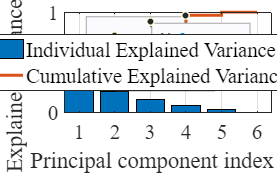

plotVE(VEi, VE, 'Principal component index (q)', 'Explained variance ratio', ["Individual Explained Variance - VEi","Cumulative Explained Variance - VE(q)"])

% tol = 0.95;
tol = 0.93;
q = find(VE<=tol);
Vq = V(:,q);

% Comparing the PCA implemented with SVD
[Usvd Lsvd Vsvd] = svd(Cx);

V

V =     0.5916    0.1001    0.0324   -0.4089   -0.2262    0.6485
    0.4671   -0.6704    0.4557    0.0160   -0.0424   -0.3501
    0.5151    0.0801   -0.4363    0.7334   -0.0058    0.0000
    0.3257    0.4433   -0.2050   -0.4006   -0.1950   -0.6759
   -0.1158   -0.5810   -0.7379   -0.2951   -0.1322   -0.0000
    0.2169    0.0046   -0.1201   -0.2168    0.9442    0.0000


diag(D)

ans =     0.0735         0         0         0         0         0
         0    0.0274         0         0         0         0
         0         0    0.0174         0         0         0
         0         0         0    0.0085         0         0
         0         0         0         0    0.0040         0
         0         0         0         0         0    0.0000


Vsvd

Vsvd =    -0.5916    0.1001    0.0324   -0.4089    0.2262   -0.6485
   -0.4671   -0.6704    0.4557    0.0160    0.0424    0.3501
   -0.5151    0.0801   -0.4363    0.7334    0.0058   -0.0000
   -0.3257    0.4433   -0.2050   -0.4006    0.1950    0.6759
    0.1158   -0.5810   -0.7379   -0.2951    0.1322    0.0000
   -0.2169    0.0046   -0.1201   -0.2168   -0.9442   -0.0000


Lsvd

Lsvd =     0.0735         0         0         0         0         0
         0    0.0274         0         0         0         0
         0         0    0.0174         0         0         0
         0         0         0    0.0085         0         0
         0         0         0         0    0.0040         0
         0         0         0         0         0    0.0000


norm(V-Vsvd)

ans = 2.0000

norm(diag(D)-Lsvd)

ans = 6.9389e-17

% PCA dimension reduction

Q = Vq';
Z = Q*X;
Cz = cov(Z')

Cz =     0.0735    0.0000   -0.0000
    0.0000    0.0274    0.0000
   -0.0000    0.0000    0.0174


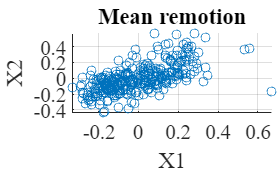

% Scatter plot analysis
X1 = X(1,:);
X2 = X(2,:);

Z1 = Z(1,:);
Z2 = Z(2,:);

plotsubscatter(X1, X2, 'X1', 'X2', 'Mean remotion')

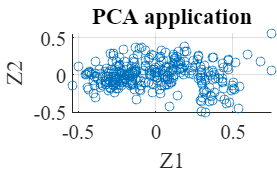


plotsubscatter(Z1, Z2, 'Z1', 'Z2', 'PCA application')

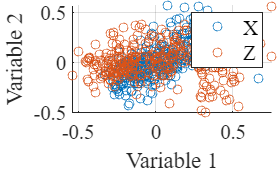


plotscatter(X1, X2, Z1, Z2, 'Variable 1', 'Variable 2', ["X","Z"])

% Matrix reconstruction
Xr = Q'*Z;

X(:,1:4)

ans =     0.0244   -0.2068    0.0804    0.0849
    0.0894   -0.1337    0.0835    0.1270
   -0.1103   -0.2408   -0.0165   -0.0682
   -0.0229   -0.1291    0.0338    0.0156
   -0.2070   -0.0378   -0.1283   -0.1726
   -0.0618   -0.0506   -0.0694   -0.0351


Xr(:,1:4)

ans =     0.0141   -0.2069    0.0613    0.0639
    0.0880   -0.1318    0.0804    0.1259
   -0.1062   -0.2257   -0.0138   -0.0461
   -0.0321   -0.1302    0.0171   -0.0039
   -0.2134   -0.0390   -0.1397   -0.1865
   -0.0298   -0.0892    0.0022   -0.0062


% Reconstruction error
err = norm(X-Xr,'fro')^2

err = 3.8666

aux1 = [];
for i=1:1:size(X,1)
    aux1(i) = norm(X(i,:)-Xr(i,:),2);
end
err_ref = sum(aux1.^2)

err_ref = 3.8666